# **MATH1019 Examples:   Wheatstone bridge circuit**

**Learning outcomes for this session**

At the end of this session, you will be able to

- Define a symbolic matrix in MATLAB.

- Use MATLAB to solve symbolically a system of linear equations.

In this example we'll solve a linear system of equations with the Symbolic Math Toolbox

# The Wheatstone bridge circuit

See  [https://en.wikipedia.org/wiki/Wheatstone_bridge](https://en.wikipedia.org/wiki/Wheatstone_bridge) for a discussion of the Wheatstone bridge.  The specific circuit that we will analyze today is shown below:

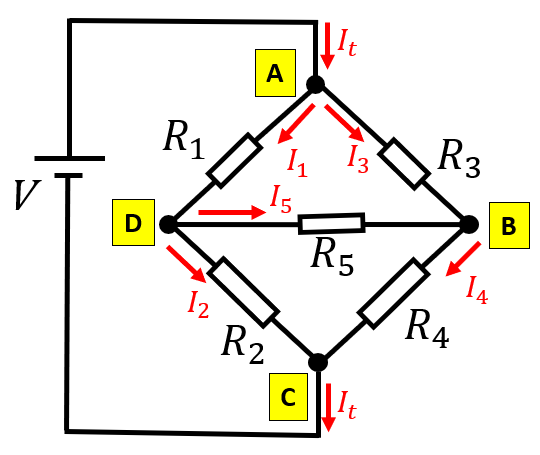

Our notation is the same as the wikipedia diagram except the resistor labelled $R_X$ in wikipedia is here denoted $R_4$.  

## Problem statement:

Given: 

- resistances, $R_j$ and voltage $V$ of the battery.

Find: 

- the currents $I_j$ flowing through resistor $R_j$

## Problem Solution:

The equations can be set up as follows. 

Apply [`Kirchhoff`s circuit law for current`](https://en.wikipedia.org/wiki/Kirchhoff's_circuit_laws) entering and leaving a Node. Consider Nodes A, D and C:

- NODE A gives us:    $I_t \;\;\;-\;\;\;I_1 \;\;-\;\;\;\;I_3 \;\;\;=\;\;0$

- NODE D gives us:    $I_1 \;\;\;-\;\;\;I_2 \;\;-\;\;\;\;I_5 \;\;=\;\;0$

- NODE C gives us:    $I_2 \;\;+\;\;\;I_4 \;\;-\;\;\;\;I_t \;\;\;=\;\;0$

Apply [`Kirchhoff`s circuit law for voltage`](https://en.wikipedia.org/wiki/Kirchhoff's_circuit_laws) drops around closed loops. This gives

- Loop VADCV gives us:          ${V\;\;\;-\;\;\;R}_1 \ldotp I_1 \;\;-\;R_2 \ldotp I_2 \;\;=\;\;0$

- Loop ABDA gives us:         $-R_3 \ldotp I_3 \;\;-\left(-R_5 \ldotp I_5 \right)\;\;-\left(-R_1 \ldotp I_1 \right)\;=\;0\;$

- Loop DBCD gives us:       $-R_5 \ldotp I_5 \;\;-R_4 \ldotp I_4 \;-\left(-R_2 \ldotp I_2 \right)\;=\;0\;$

The preceeding give a system of 6 linear equations in the 6 unknown currents (ie:  $I_t \;,I_1 \;,I_2 \;,I_3 \;,I_4 \;,I_5$ ).  

- 
$$\left\lbrack \begin{array}{cccccc}
-1 & 0 & -1 & 0 & 0 & 1\\
1 & -1 & 0 & 0 & -1 & 0\\
0 & 1 & 0 & 1 & 0 & -1\\
-R_1  & -R_2  & 0 & 0 & 0 & 0\\
R_1  & 0 & -R_3  & 0 & R_5  & 0\\
0 & R_2  & 0 & -R_4  & -R_5  & 0
\end{array}\right\rbrack \ldotp \left\lbrack \begin{array}{c}
I_1 \\
I_2 \\
I_3 \\
I_4 \\
I_5 \\
I_t 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0\\
0\\
-V\\
0\\
0
\end{array}\right\rbrack$$


Which has the form:

- $A_W \;\ldotp I_W =b_W$       where     $I_W ={\left\lbrack \begin{array}{cccccc}
I_1  & I_2  & I_3  & I_4  & I_5  & I_t 
\end{array}\right\rbrack }^T$

MATLAB with the Symbolic Math Toolbox has no difficulty solving this.

syms I_1  I_2  I_3  I_4  I_5  I_t  V
syms R_1  R_2  R_3  R_4  R_5

A_w = [    -1,    0,   -1,    0,    0,  1;
            1,   -1,    0,    0,   -1,  0;
            0,    1,    0,    1,    0, -1;
         -R_1, -R_2,    0,    0,    0,  0;
          R_1,    0, -R_3,    0,  R_5,  0;
          0  ,  R_2,    0, -R_4, -R_5,  0; ];
      
b_w = [0;0;0;-V;0;0]

$$b\_w = \left(\begin{array}{c} 0\\ 0\\ 0\\ -V\\ 0\\ 0 \end{array}\right)$$


I_w = A_w \ b_w

$$I\_w = \begin{array}{l} \left(\begin{array}{c} \frac{R_{2}\,R_{3}\,V+R_{3}\,R_{4}\,V+R_{3}\,R_{5}\,V+R_{4}\,R_{5}\,V}{\sigma_{1}}\\ \frac{R_{1}\,R_{4}\,V+R_{3}\,R_{4}\,V+R_{3}\,R_{5}\,V+R_{4}\,R_{5}\,V}{\sigma_{1}}\\ \frac{R_{1}\,R_{2}\,V+R_{1}\,R_{4}\,V+R_{1}\,R_{5}\,V+R_{2}\,R_{5}\,V}{\sigma_{1}}\\ \frac{R_{1}\,R_{2}\,V+R_{2}\,R_{3}\,V+R_{1}\,R_{5}\,V+R_{2}\,R_{5}\,V}{\sigma_{1}}\\ -\frac{V\,\left(R_{1}\,R_{4}-R_{2}\,R_{3}\right)}{\sigma_{1}}\\ \frac{V\,\left(R_{1}\,R_{2}+R_{1}\,R_{4}+R_{2}\,R_{3}+R_{1}\,R_{5}+R_{2}\,R_{5}+R_{3}\,R_{4}+R_{3}\,R_{5}+R_{4}\,R_{5}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,R_{4}+R_{1}\,R_{3}\,R_{4}+R_{1}\,R_{3}\,R_{5}+R_{2}\,R_{3}\,R_{4}+R_{1}\,R_{4}\,R_{5}+R_{2}\,R_{3}\,R_{5}+R_{2}\,R_{4}\,R_{5} \end{array}$$

And checking our answer:  does $A_W \;\ldotp I_W$ really gives us $b_W$ ?

should_be_bw = simplify(A_w * I_w)

$$should\_be\_bw = \left(\begin{array}{c} 0\\ 0\\ 0\\ -V\\ 0\\ 0 \end{array}\right)$$

## A Practical use of the wheatstone circuit:

Given three known resistors $R_1 ,R_2 ,R_3$ and at least one adjustable callibrated resistor $R_5$, the value of an **unknown resistor **$R_4$ can be determined.  A way to do this, is to adjust the adjustable resistor $R_5$ so that current $I_5$ showing on an ammeter is zero.   Recall our expression for $I_5$ :

I_w(5)

$$ans = -\frac{V\,\left(R_{1}\,R_{4}-R_{2}\,R_{3}\right)}{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,R_{4}+R_{1}\,R_{3}\,R_{4}+R_{1}\,R_{3}\,R_{5}+R_{2}\,R_{3}\,R_{4}+R_{1}\,R_{4}\,R_{5}+R_{2}\,R_{3}\,R_{5}+R_{2}\,R_{4}\,R_{5}}$$

So if we can adjust $R_5$ such that $0=I_5$, then we can determine the unknown resistor $R_4$.

solve( 0==I_w(5),  R_4)

$$ans = \frac{R_{2}\,R_{3}}{R_{1}}$$

So in summary,  if we know $R_1 ,R_2 ,R_3$ and if we can adjust $R_5$ until we produce $0=I_5$ , then this condition allows us to determine $R_4$ as:

- 
$$R_4 =\frac{R_2 \;\ldotp R_3 }{R_1 }$$
